# Modeling & Simulation Using S-Domain (LaPlace Transform) 

## Task #1. Understand the Project Scope

In today's project, we will learn how to represent the system in the Laplace Transform or what's called as S-Domain.

Laplace transform is an integral transform that converts a function from the time domain to complex frequency domain or what's named as S-domain. 

Laplace Transform is used to solve differential equations and make them much easier to solve. It converts linear differential equations into algebraic equations and convolutions into multiplications.  

Recall that system modeling is used to map the reality (real dynamic system such as a car) into a set of simplified mathematical equations (model). A system model is a set of governing mathematical equations which describe the model's dynamical behavior.

Once you have a governing mathematical equations, you can then simulate the system and assess its performance using simulation tools such as Matlab/Simulink.

The dynamics of many systems, whether they are mechanical, electrical, thermal, economic, biological, etc., may be described in terms of differential equations. Such differential equations may be obtained by using physical laws such as Newton's laws for mechanical systems or Kirchhoff's laws for electrical systems. 

Consider a simple mass spring damper system as shown below:

               Assume M = 1 Kg, b = 1 Ns/m, k =1 N/m

                                                                             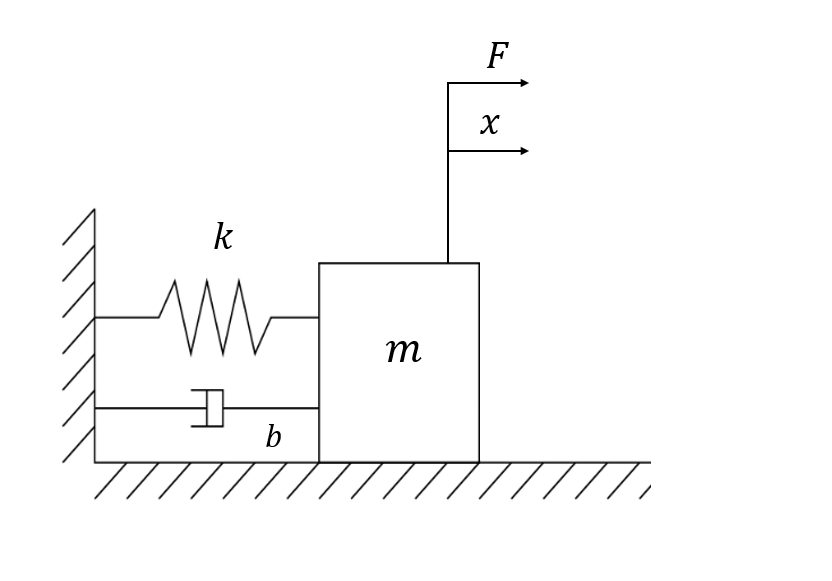

## Task #2: Understand Laplace Transform

A system represented by a differential equation is difficult to model as a block diagram. Therefore, Laplace transform represents input, output, and system as separate entities with algebraic relationships. 

Laplace transform drastically simplifies the representation of physical systems.

The function F(s) is a function of the Laplace variable "s."  We call this a Laplace domain function.  

Laplace Transform takes a time domain function f(t) and converts it into a Laplace domain function F(s). 

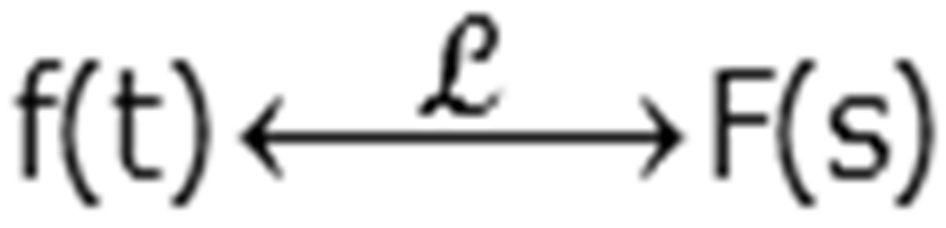

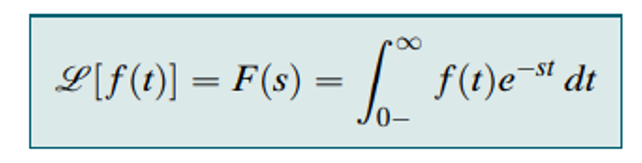

Example: Find the Laplace Transform for the following function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{t}}\right)={\mathit{\mathbf{e}}}^{\mathit{\mathbf{t}}\;}$

The Laplace transform of a signal (function) f is defined by: 

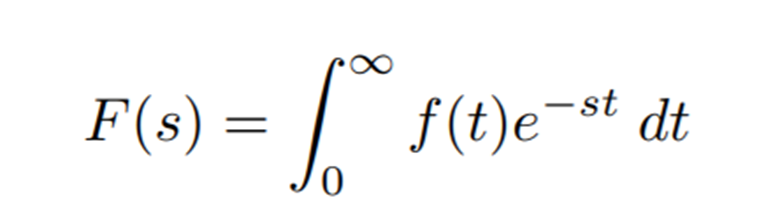

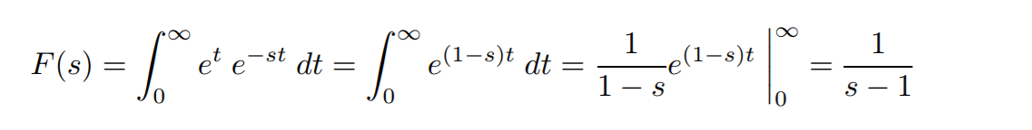

## **Practice Opportunity #1:**

Obtain the Laplace transform of a signal (function) f that is defined by: 

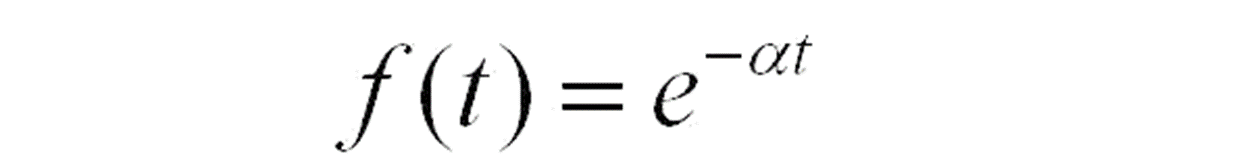

## Task #3: Apply Laplace Transform and Obtain the Transfer Function

The *transfer function *of a linear, time-invariant, differential equation system is the ratio of the Laplace transform of the output to the Laplace transform of the input.

Initial conditions are assumed to be zero.

The *transfer function* is the mathematical model of the system.

The highest power of *s *in the denominator is the order of the systemLaplace domain allows for system representation in a compact transfer function form.

                                                                                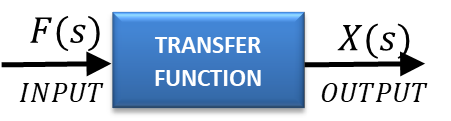

The first step in obtaining the transfer function is to apply Laplace Transform to the system as follows:

                                                                                    
$$\textrm{Mx}̈=F-\textrm{bx}̇-\textrm{kx}$$


                                                                        
$${\textrm{Ms}}^{2\;} X\left(s\right)=F\left(s\right)-\textrm{bsX}\left(s\right)-\textrm{kX}\left(s\right)$$


                                                                                        
$$\frac{X\left(s\right)}{F\left(s\right)}=\frac{1}{{\textrm{Ms}}^2 +\textrm{bs}+k}$$


The Laplace Transform table is as shown below:

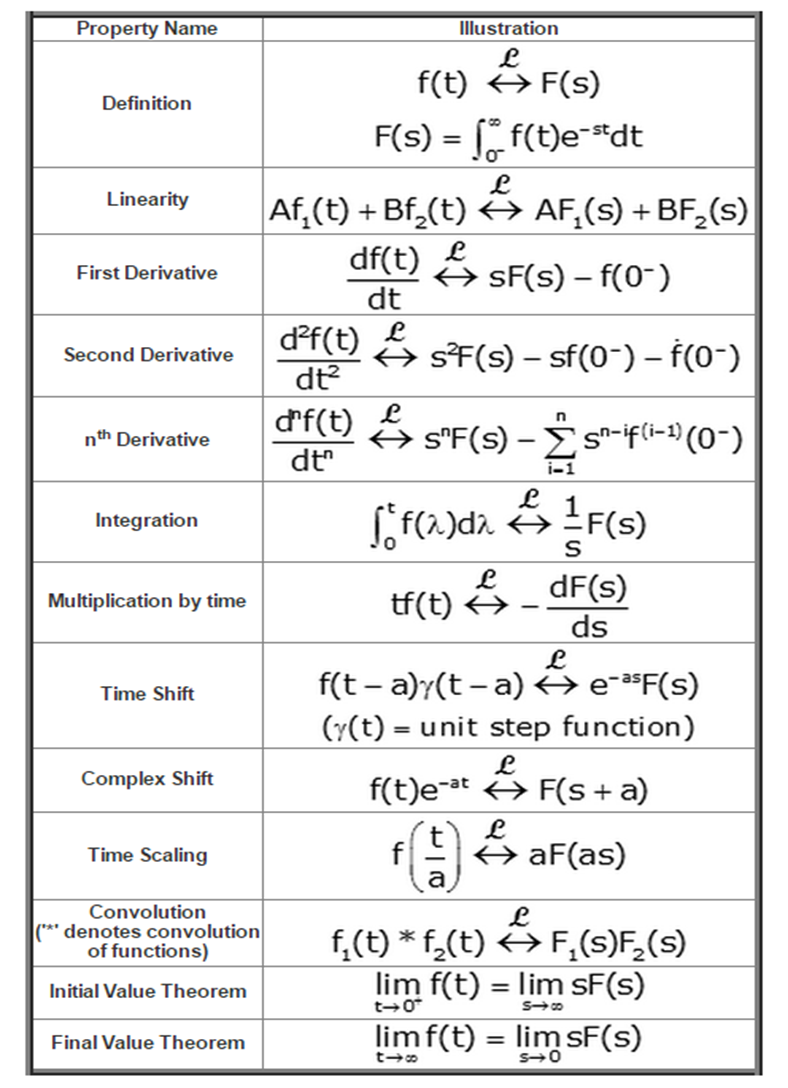

## Task #4: Build Simulink Model (Transfer Function)

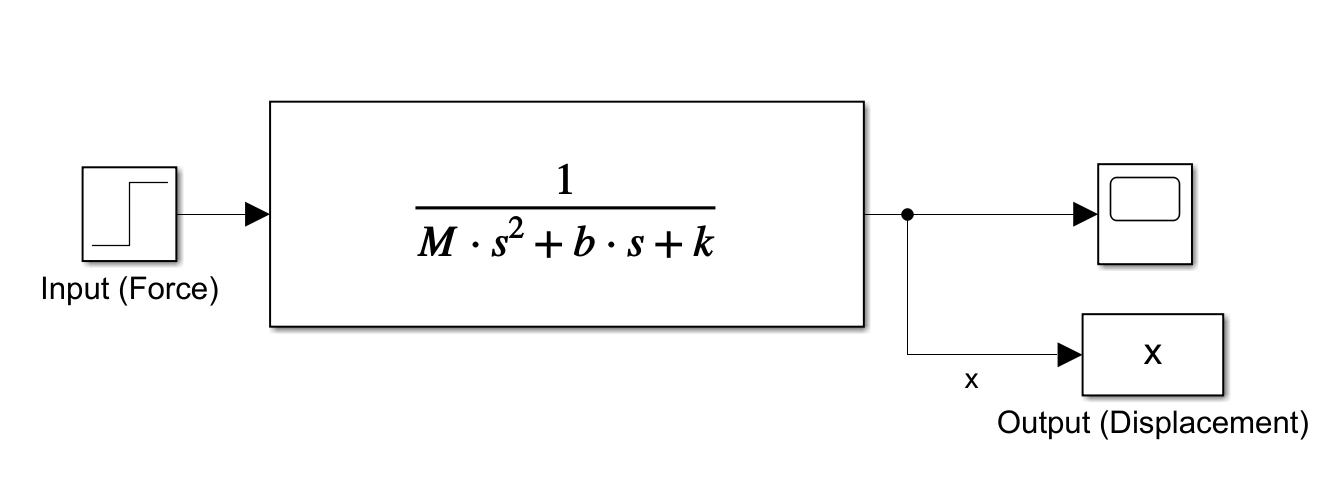

## **Task #5: Simulate the System Using Transfer Functions**

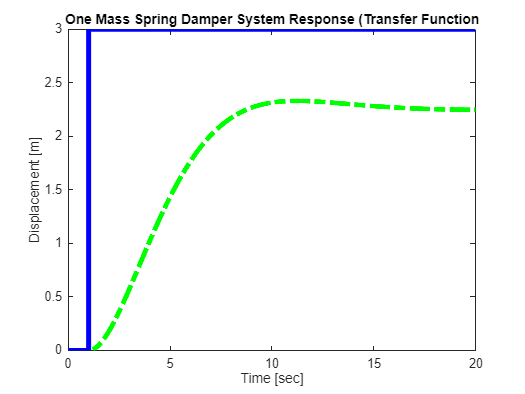

% Define Model Parameters
Sim_Time = 20;
F = 3;
M = 20;
b =13;
k = 4;
sim('problem2_translation_system');

figure
plot(x,'-.g','LineWidth',4)

hold on 
plot(F, 'b', 'LineWidth',4)

ylabel('Displacement [m]')
xlabel('Time [sec]')
title('One Mass Spring Damper System Response (Transfer Function')

## Final Capstone Project Overview

In this final capstone project, please complete the following tasks: 

- Obtain the transfer functions $X_{1\;} \left(s\right)/\left(F\left(s\right)\right)$ and $X_{2\;} \left(s\right)/\left(F\left(s\right)\right)$ for the system below

- Build a two degrees of freedom mechanical system using transfer function blocks in Simulink. Note that the systems contains two masses m1 and m2, two springs with spring constants k1 and k2, and two dampers with damping coefficients b1 and b2. 

                                                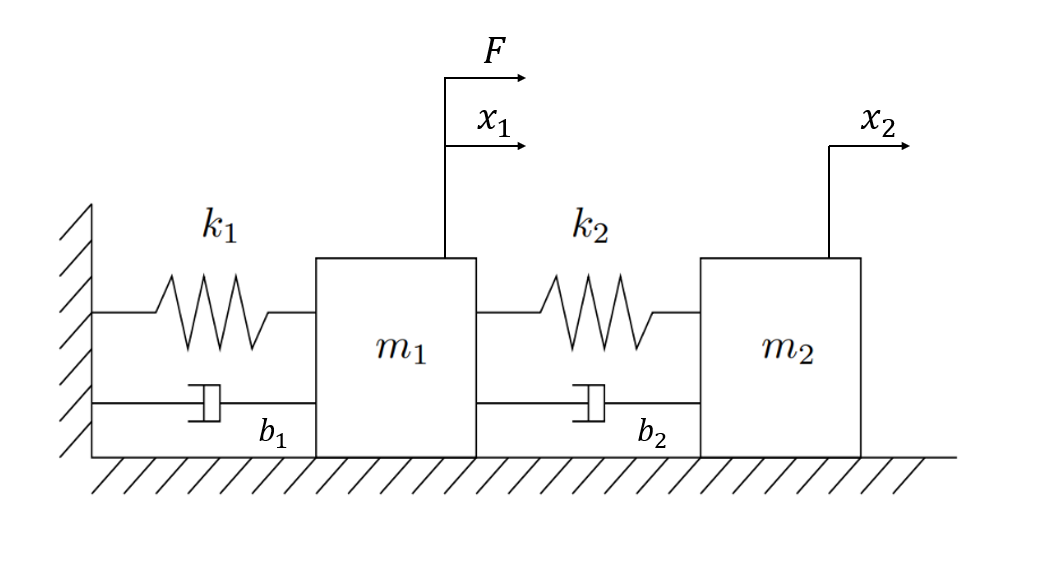

        3. Assuming m1 = 1 Kg, b1 = 1 Ns/m, k1 = 1 N/m, m2 = 1 Kg, b2 = 1 Ns/m, k2 = 1 N/m, apply a unit step input F and simulate the system. 

        4. Plot the displacement x1, x2, and Force (input) on one graph.

        5. Assume that the system has no damping element, simulate the system and comment on the results. 

## Final Capstone Project Solution

Using Newton's Second law of motion, the system can be described by the following equations:

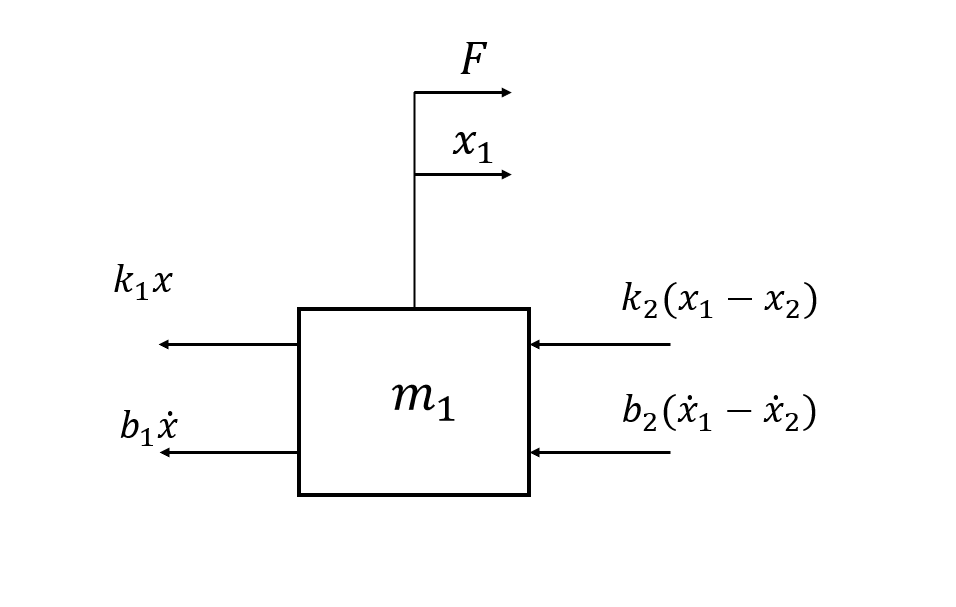

                                                             
$$m_1 \ddot{x_{1\;} } =F-b_{1\;} \dot{x_{1\;} } -k_{1\;} x_{\;1} -k_{\;2} \left(x_1 -x_{2\;} \right)-b_{2\;} \left(\dot{x_{\;1} } -\dot{x_{\;2} } \right)$$


                            
$$m_{1\;} s^{2\;} X_1 \left(s\right)=F\left(s\right)-b_{1\;} {\textrm{sX}}_1 \left(s\right)-k_{1\;} X_{\;1} \left(s\right)-k_{2\;} \left\lbrack X_{\;1} \left(s\right)-X_{2\;} \left(s\right)\right\rbrack -b_{2\;} \left\lbrack sX_{\;1} \left(s\right)-sX_{2\;} \left(s\right)\right\rbrack$$


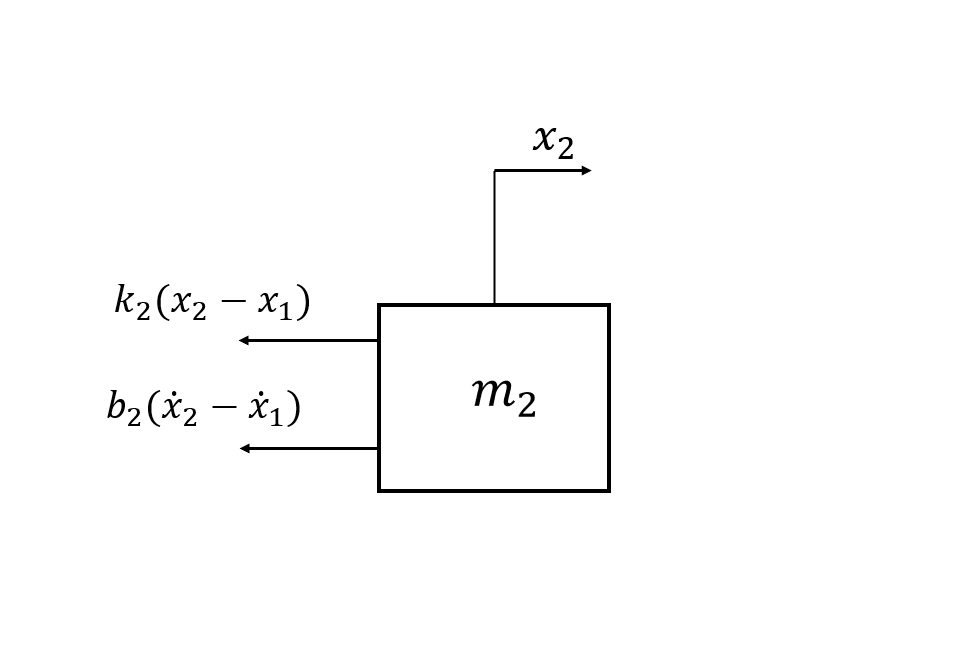


$$m_2 \ddot{x_{2\;} } =-k_{\;2} \left(x_2 -x_{1\;} \right)-b_{2\;} \left(\dot{x_{\;2} } -\dot{x_{\;1} } \right)$$



$$m_{2\;} s^{2\;} X\left(s\right)=-k_{\;2} \left\lbrack X_{2\;} \left(s\right)-X_{1\;} \left(s\right)\right\rbrack -b_{\;2} s\left\lbrack X_{2\;} \left(s\right)-X_{1\;} \left(s\right)\right\rbrack$$


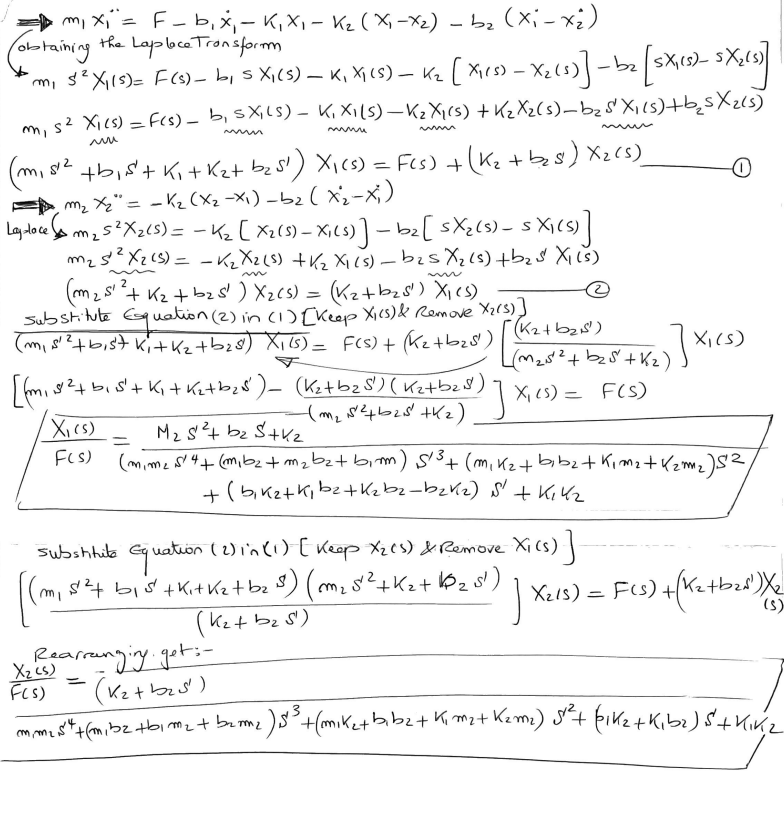

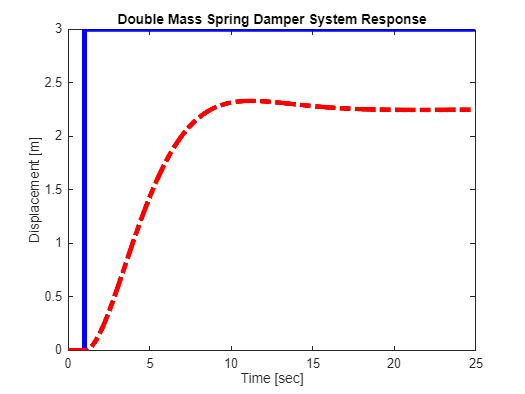

% Define Model Parameters
Sim_Time = 25;
F = 3;
M1 = 20;
b1 =13;
k1 = 4;

M2 = 1;
b2 =0;
k2 = 1;

sim('problem2_translation_system');
figure
plot(x,'--g','LineWidth',4)

hold on 
plot(F, 'b', 'LineWidth',4)
hold on 
plot(x,'-.r','LineWidth',4)
ylabel('Displacement [m]')
xlabel('Time [sec]')
title('Double Mass Spring Damper System Response')

## Great Job!

## **Practice Opportunity #1 Solution:**

Obtain the Laplace transform of a signal (function) f that is defined by: